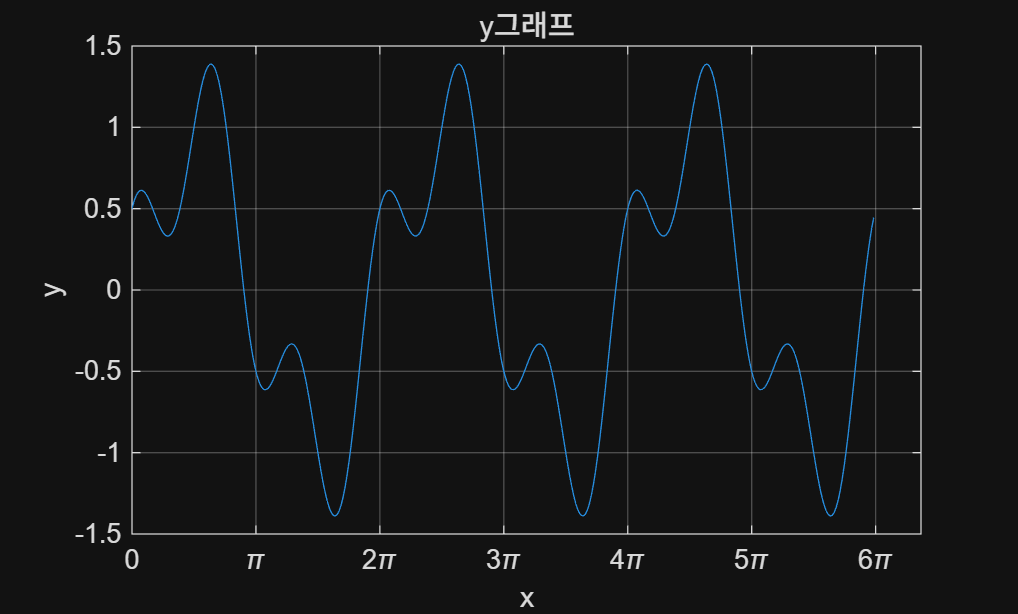

%%1

x=0:0.05:6*pi;
y=sin(x)+0.5*cos(3*x);
plot(x,y)
xticks(0:pi:6*pi)
xticklabels({'0','\pi','2\pi','3\pi','4\pi','5\pi','6\pi'})
title('y그래프')
xlabel('x')
ylabel('y')
grid on

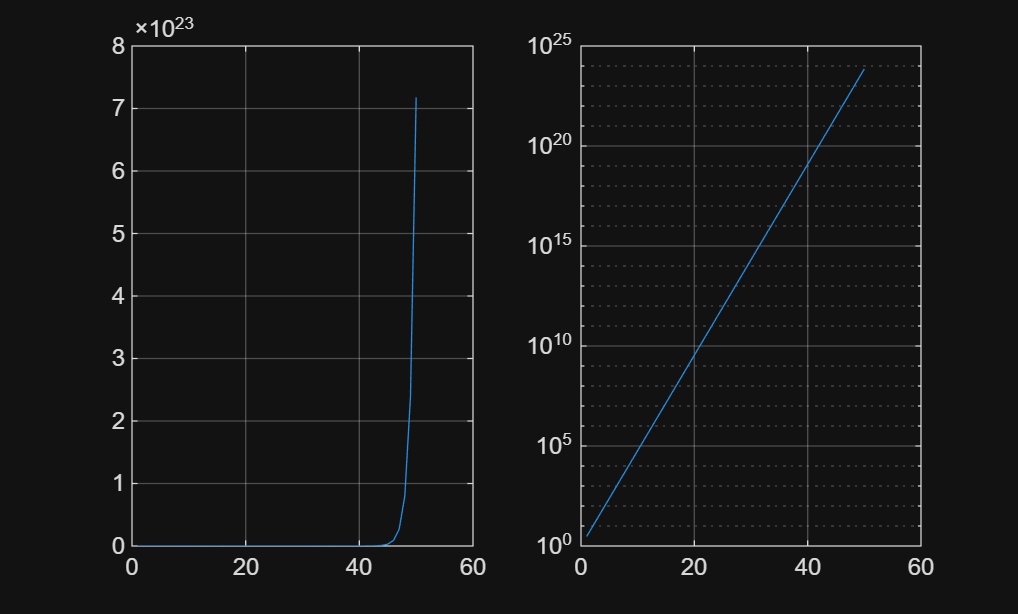

%2

x=1:1:50;
y=3.^x;
subplot(1,2,1)
plot(x,y)
grid on
subplot(1,2,2)
semilogy(x,y)
grid on



%일반>> 함수가 지수적으로 증가함
%semi>> 로그스케일로 나타나서 함수가 직선이 나옴

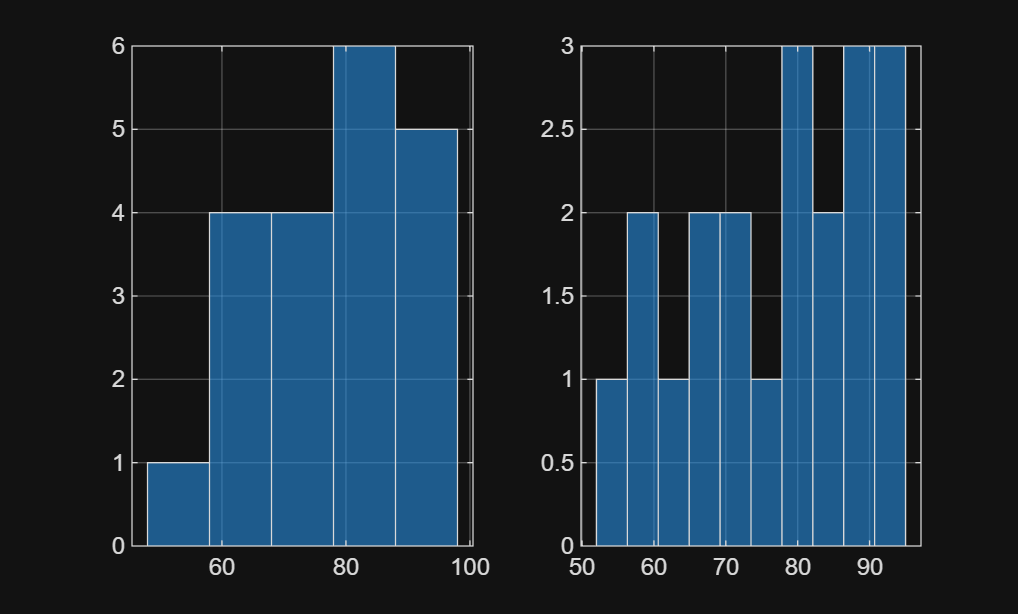

%%3



s=[72,85,91,66,78,88,95,54,60,73,82,90,69,77,84,92,58,63,79,87];
save score.dat s -ascii
a=load('score.dat');
subplot(1,2,1)
histogram(a,5)
grid on
subplot(1,2,2)
histogram(a,10)
grid on

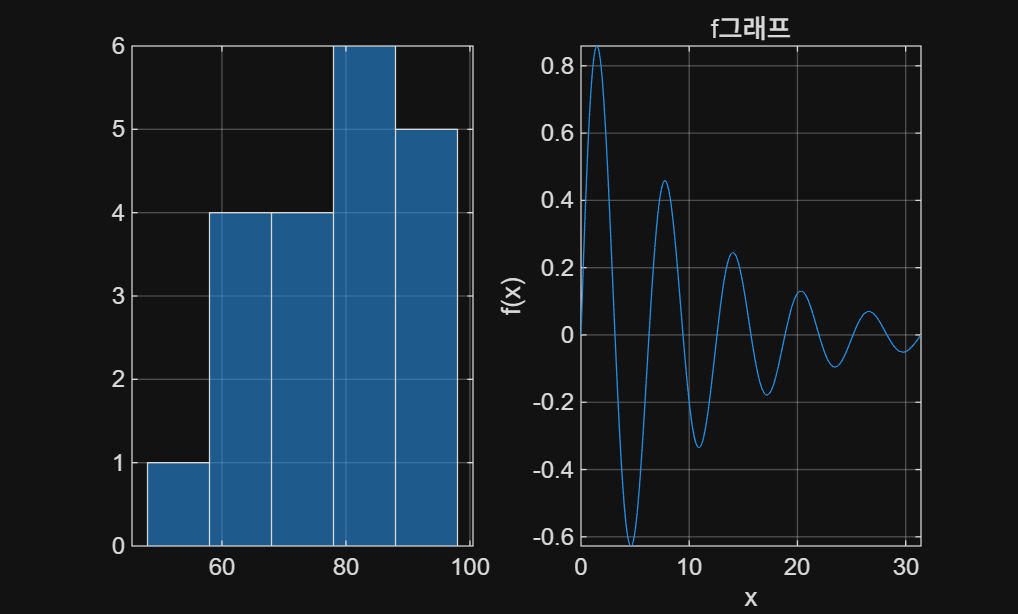

%%4


f=@(x)sin(x).*exp(-0.1*x);
fplot(f,[0 10*pi])
title('f그래프')
xlabel('x')
ylabel('f(x)')
grid on

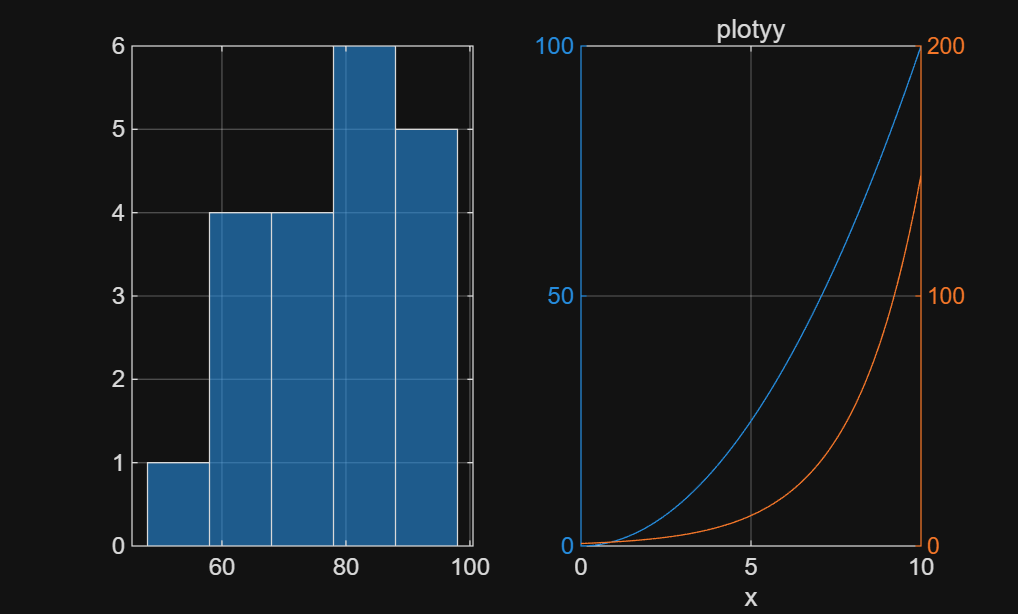

%% 5번


x=0:0.1:10;
y=x.^2;
z=exp(0.5*x);
plotyy(x,y,x,z)
title('plotyy')
xlabel('x')
grid on


% y>> 2차함수이고 곡선형태로 증가합니다
% z>> 지수함수이기 때문에 뒤로갈수록 2차보다 더 급격하게 증가합니다.

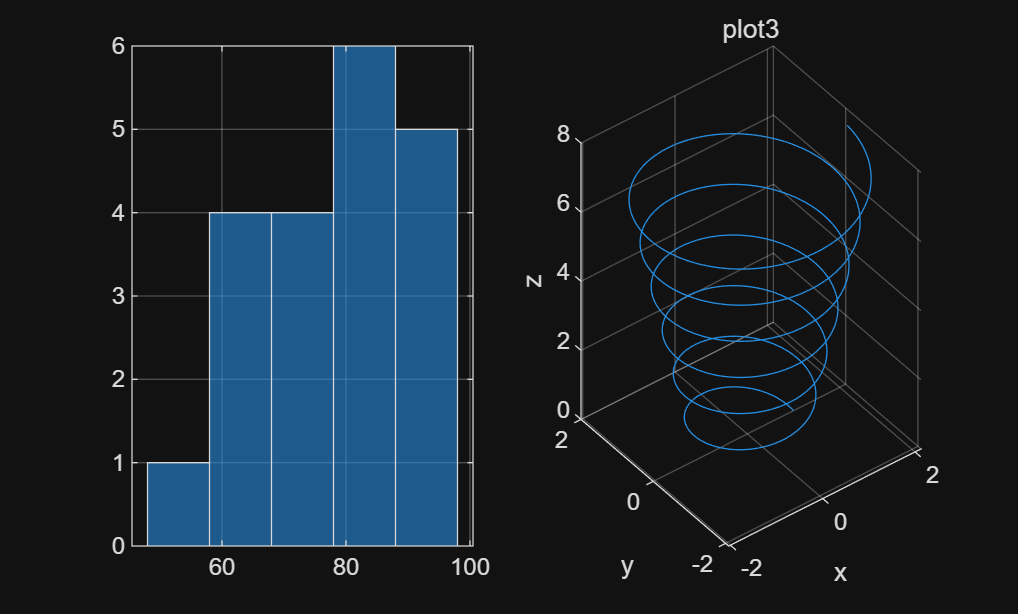

%% 6번

t=0:0.02:12*pi;
x=(1+0.03*t).*cos(t);
y=(1+0.03*t).*sin(t);
z=0.2*t;
plot3(x,y,z)
title('plot3')
xlabel('x')
ylabel('y')
zlabel('z')
grid on

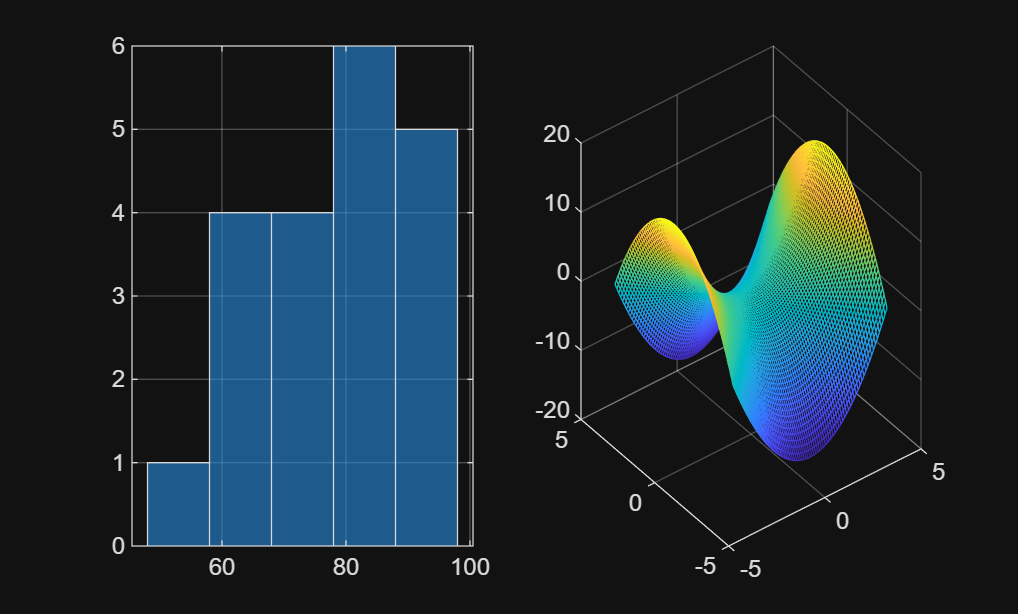

%% 7번

x=-4:0.1:4;
y=-4:0.1:4;
[X,Y]=meshgrid(x,y);
Z=X.^2-Y.^2;
mesh(X,Y,Z)
grid on


%x방향으로는 위로 휘고 y방향으로는 아래로 휘기 때문에
%한방향에서는 증가하고 다른 방향에서는 감소하는 안장 모양이라 saddle surface입니다.


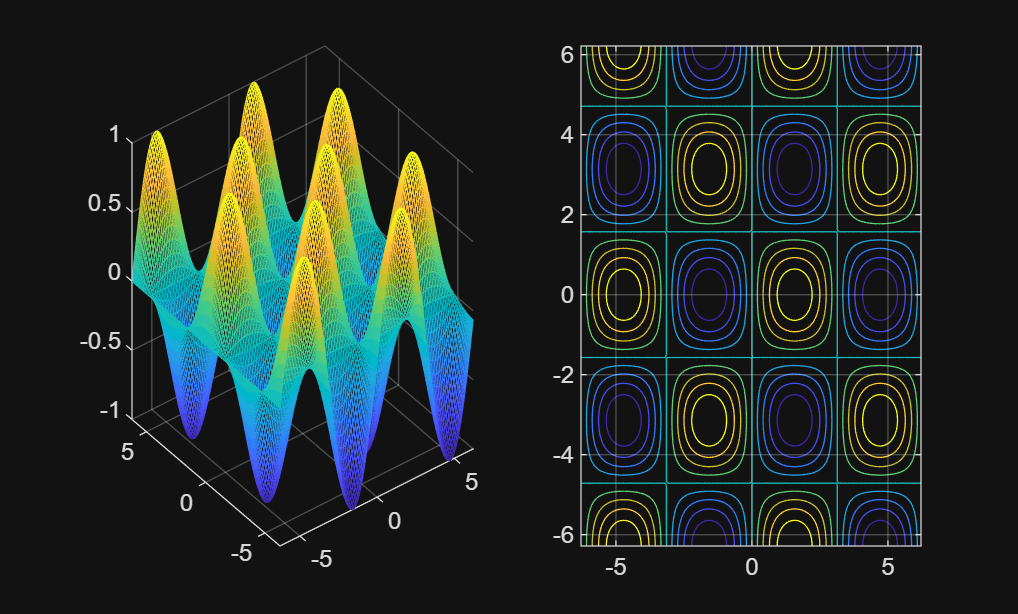

%% 8번

x=-2*pi:0.1:2*pi;
y=-2*pi:0.1:2*pi;
[X,Y]=meshgrid(x,y);
Z=sin(X).*cos(Y);
subplot(1,2,1)
mesh(X,Y,Z)
grid on
subplot(1,2,2)
contour(X,Y,Z)
grid on


%contour>>등고선처럼 z값이 같으면 선으로 연결합니다. 
%그러므로 3차원 함수의 높낮이를 2차원에서 확인할 수 있습니다



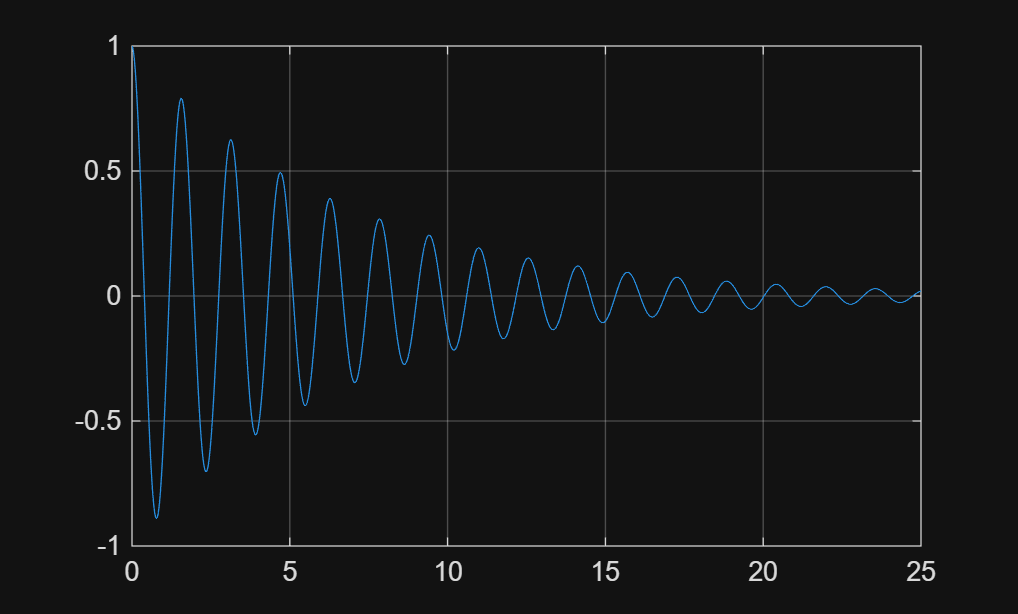

%% 9번


t=0:0.01:25;
y=exp(-0.15*t).*cos(4*t);
a=exp(-0.15*t);
b=-exp(-0.15*t);
figure

%a
plot(t,y)
grid on

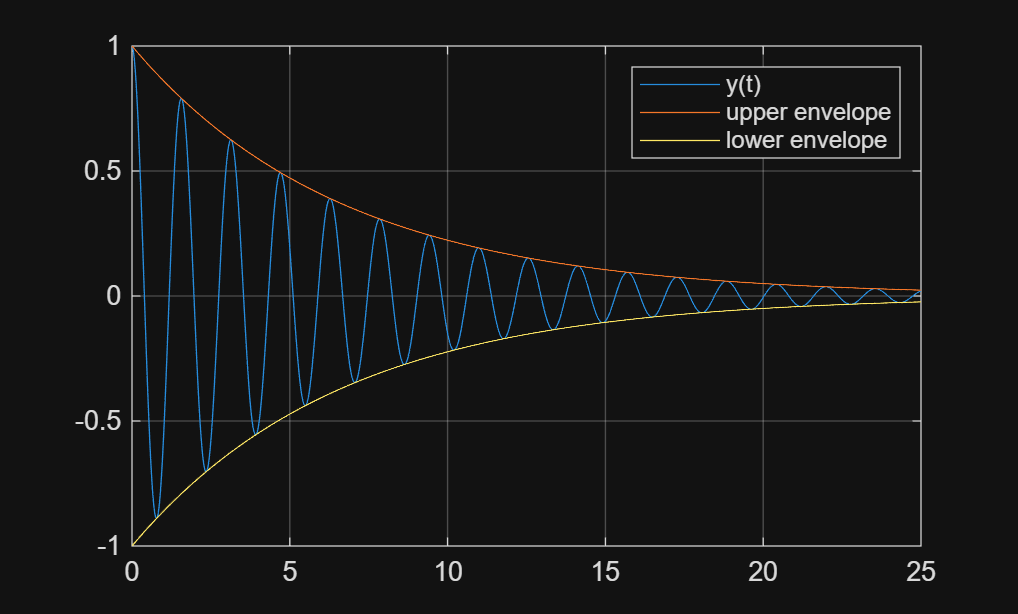



%b
figure
plot(t,y,t,a,t,b)
legend('y(t)','upper envelope','lower envelope')
grid on

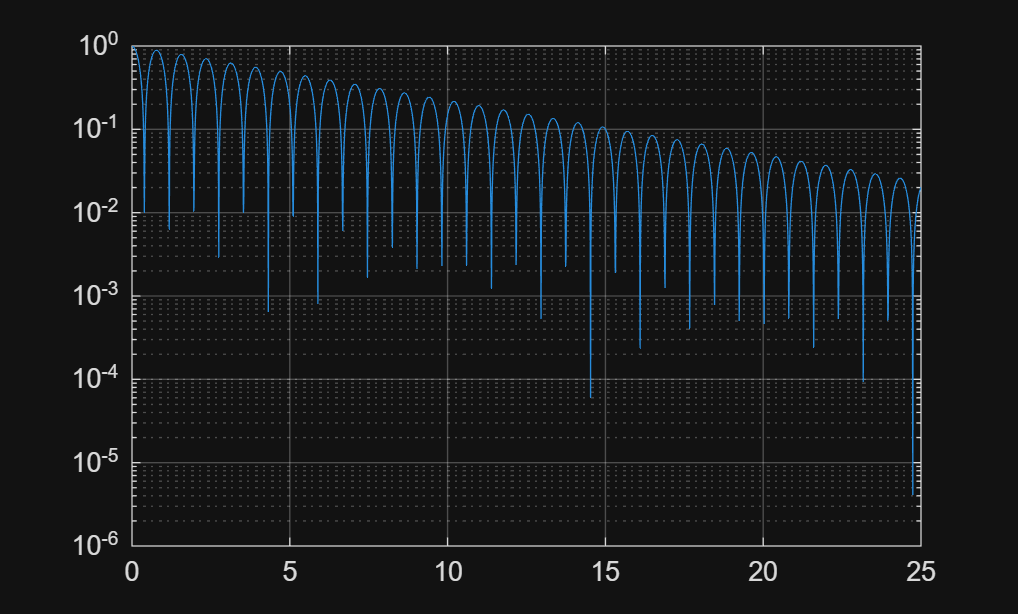


%%c
figure
semilogy(t,abs(y))
grid on



%로그스케일에서는 감쇠하는 크기 변화가 더 잘 보이고, 전체적으로 직선입니다.



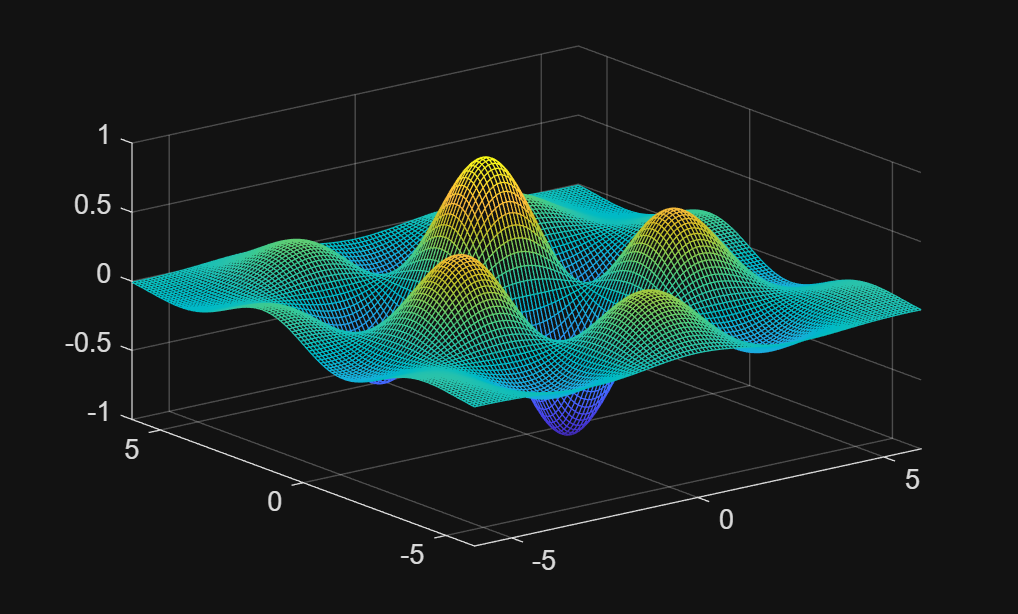

%%10

x=-6:0.1:6;
y=-6:0.1:6;
[X,Y]=meshgrid(x,y);
Z=cos(X).*sin(Y).*exp(-0.05*(X.^2+Y.^2));
figure
mesh(X,Y,Z)
grid on

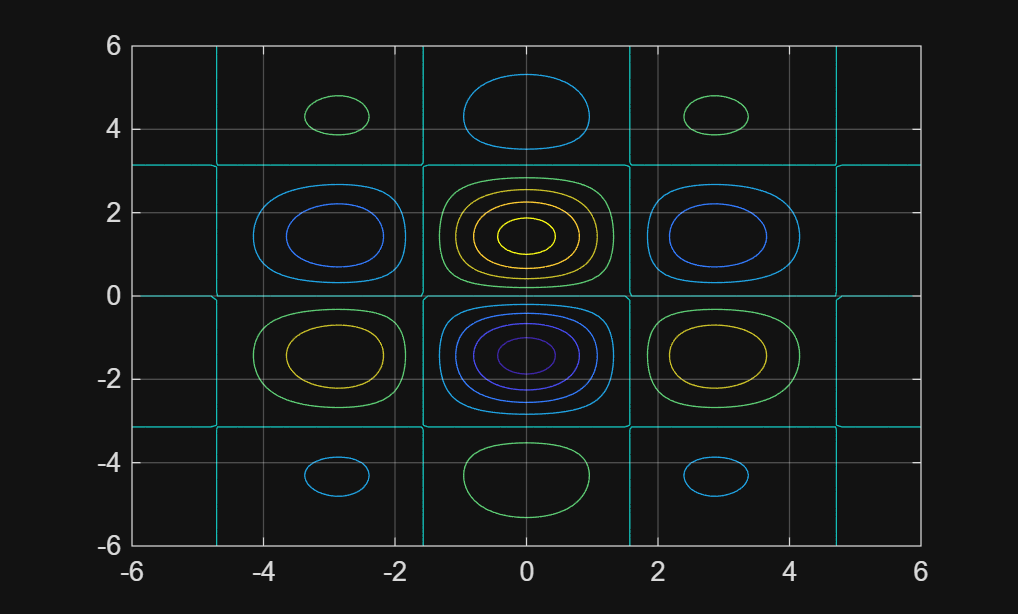


figure
contour(X,Y,Z)
grid on


[a,b]=max(Z(:));
c=X(b);
d=Y(b);

fprintf('z의 최대값=%.4f\n',a)

z의 최대값=0.8935


fprintf('x 위치=%.4f\n',c)

x 위치=0.0000


fprintf('y 위치=%.4f\n',d)

y 위치=1.4000


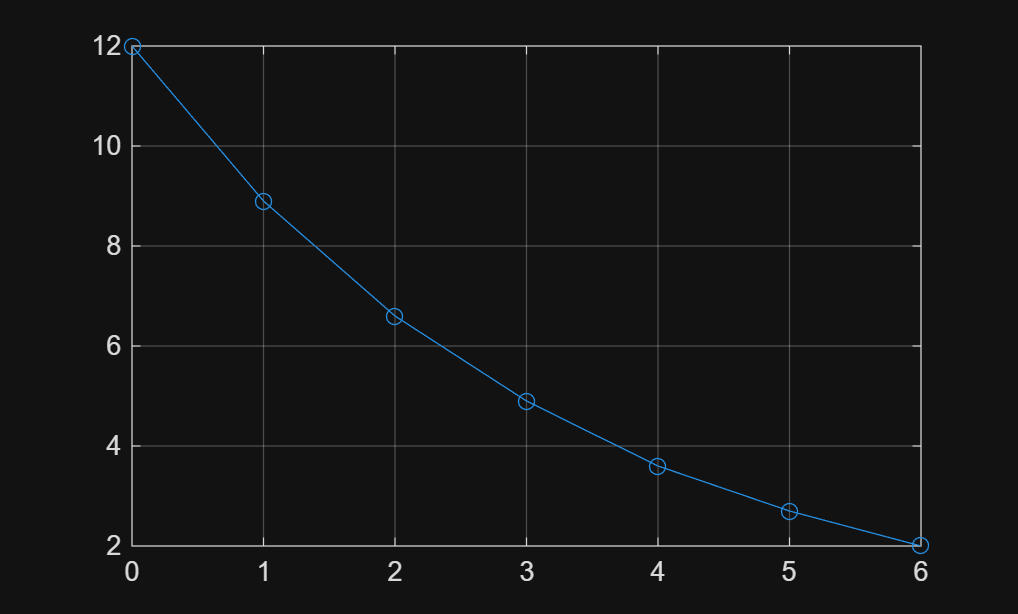

%11


t=[0,1,2,3,4,5,6];
C=[12,8.9,6.6,4.9,3.6,2.7,2.0];
plot(t,C,'o-')
grid on

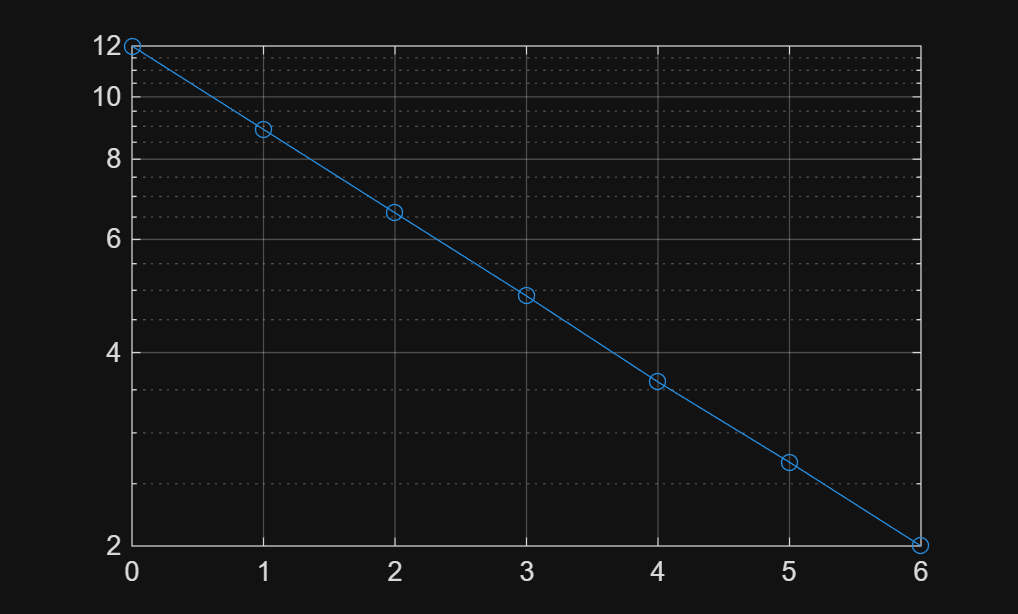



figure
semilogy(t,C,'o-')
grid on


a=polyfit(t,log(C),1);
k=-a(1);
fprintf('k==%.4f\n',k)

k==0.2988


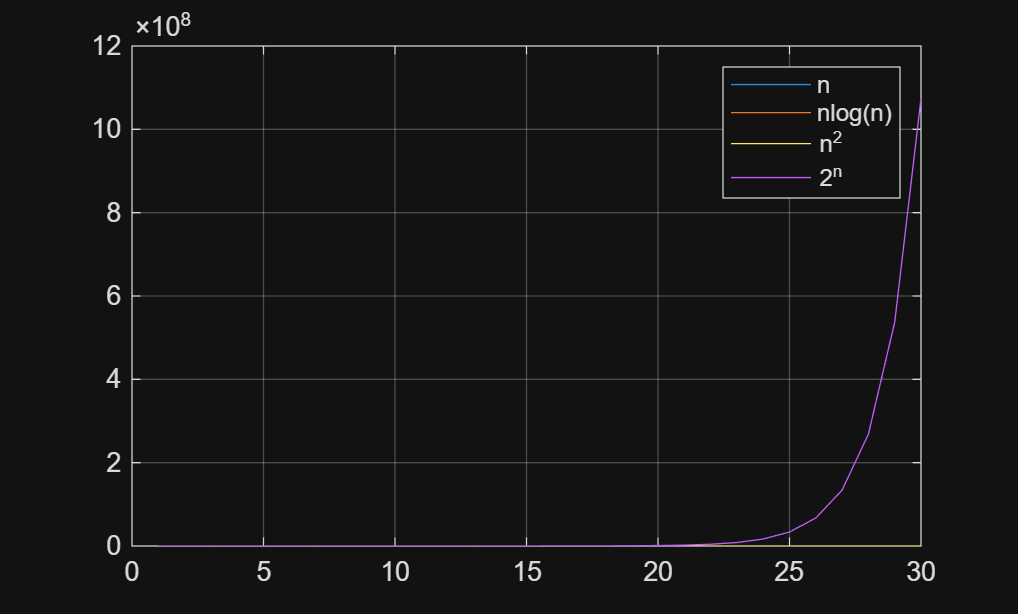

%%12


n=1:1:30;
a=n;
b=n.*log(n);
c=n.^2;
d=2.^n;

figure
plot(n,a,n,b,n,c,n,d)
legend('n','nlog(n)','n^2','2^n')
grid on

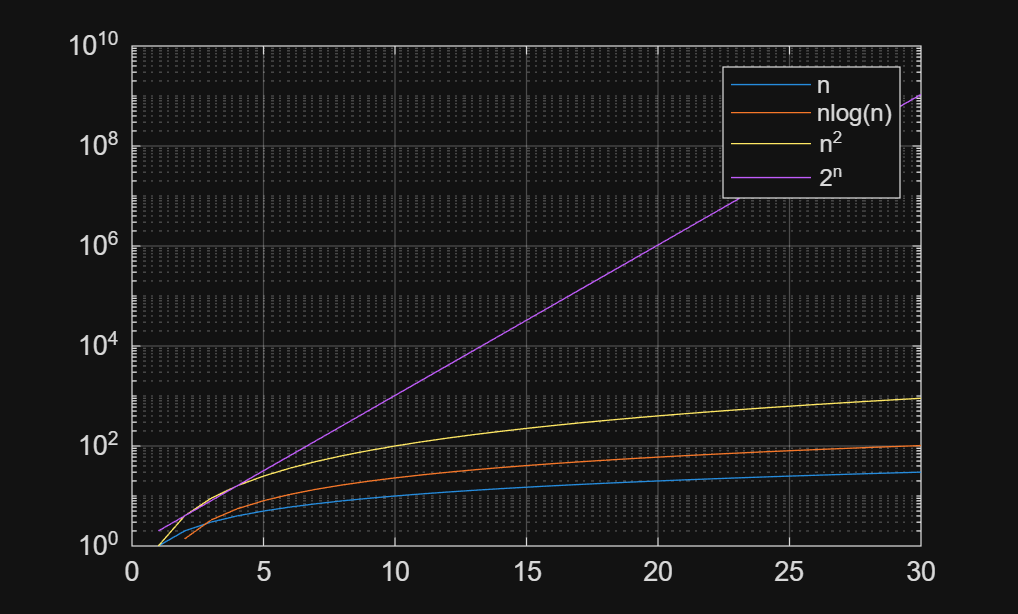


figure
semilogy(n,a,n,b,n,c,n,d)
legend('n','nlog(n)','n^2','2^n')
grid on



%일반에서는 값 증가가 빨라서 크기차이 비교가 힘들고 semilogy에서는 로그스케일이기 때문에
%차이 비교에 더 용이합니다.


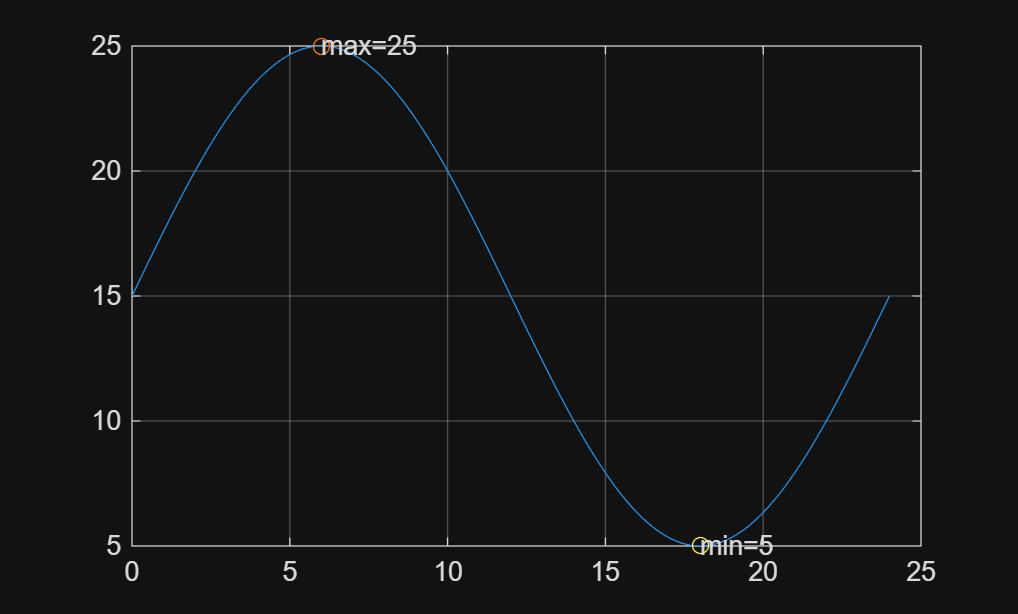

%16

t=0:0.1:24;
T=15+10*sin(pi*t/12);
[a,b]=max(T);
[c,d]=min(T);
plot(t,T)
hold on
plot(t(b),a,'o')
plot(t(d),c,'o')
text(t(b),a,['max=',num2str(a)])
text(t(d),c,['min=',num2str(c)])
hold off
grid on

%%17



t=0:0.1:20;
v=5*exp(-0.2*t);
figure
plot(t,v)
grid on

figure
semilogy(t,v)
grid on


%일반은 곡선 형태로 감소하고 semilogy에서는 로그스케일이므로 직선형태로 나타납니다.


%%18

A=[4 -1 2;1 3 -1;2 -2 5];
b=[7;4;10];
a=A^2;
c=A.^2;
d=det(A);
e=inv(A)*b;
f=A\b;

disp('A^2')
disp(a)
disp('A.^2')
disp(c)
disp('det(A)')
disp(d)
disp('inv(A)*b')
disp(e)
disp('A\b')
disp(f)

%A^2는 행렬곱이고 A.^2는 원소를 제곱한 결과입니다.
%또한 det(A)가 0이 아니면 A의 역행렬이 존재하므로 역행렬을 가집니다.
%inv(A)*b와 A\b는 모두 Ax=b의 해를 구하는 방법입니다.하지만 보통 A\b를 사용합니다.


%%19


A=[2 -1;3 4];
B=[1 0 -2;3 5 1];
C=[6 -3 4;15 14 -1];
D=C-B;
X=A\D;

disp('C-B')
disp(D)
disp('X')
disp(X)
disp('AX+B')
disp(A*X+B)
disp('C')
disp(C)



%%20


X=[3 7 2 5;5 9 4 6;8 12 7 10;10 15 9 13;14 18 12 16];
a=mean(X);
b=X-a;
S=b'*b;

disp('mean(X)')
disp(a)
disp('Xc')
disp(b)
disp('S')
disp(S)

